clear all;

i_SET = 0:45:315;%8 directions
VS = 4; %90 degree
ES = 6; %225 degree
x_SET = 0:10:100; % coherence level

bel = zeros(size(i_SET,2), size(x_SET,2)); % belief distribution
alpha = zeros(size(i_SET,2),1);
y = zeros(size(i_SET,2), size(x_SET,2));
beta = 1*ones(size(i_SET,2),1);
p = zeros(size(i_SET,2), size(x_SET,2));

for i_idx = 1:size(i_SET,2) % direction
    if i_idx == ES
        z1 = 1; % only for microstimulation
    else
        z1 = 0;
    end
    
    gamma_d = abs(VS - i_idx);
    
    for x_idx = 1: size(x_SET,2) % coherence level
        y(i_idx, x_idx) = alpha(i_idx) + beta(i_idx)*z1 +(6-gamma_d) * x_SET(x_idx)/100;
        % 5-gamma_d: inverse proportaional to gamma_d
    end    
end



for x_idx = 1: size(x_SET,2)
    %for i_idx = 1:size(i_SET,2) % direction
    p(:, x_idx) = exp(y(:, x_idx))./ sum(exp(y(:, x_idx)));
    %end
end


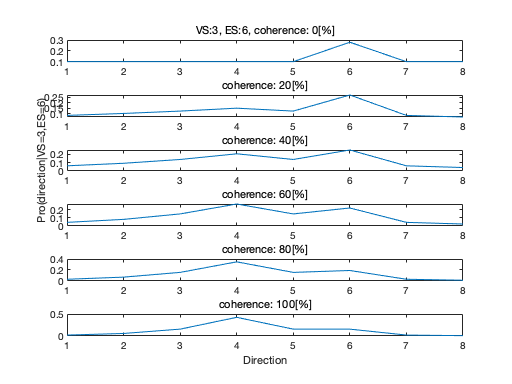


figure;
subplot(6,1,1);
plot(p(:,1));
title(['VS:3, ES:6, coherence: ',num2str(x_SET(1)),'[%]']);


subplot(6,1,2); 
plot(p(:,3));
title(['coherence: ',num2str(x_SET(3)),'[%]']);

subplot(6,1,3);
plot(p(:,5));
title(['coherence: ',num2str(x_SET(5)),'[%]']);
ylabel('Pro(direction|VS=3,ES=6)');
subplot(6,1,4);
plot(p(:,7));
title(['coherence: ',num2str(x_SET(7)),'[%]']);

subplot(6,1,5); 
plot(p(:,9));
title(['coherence: ',num2str(x_SET(9)),'[%]']);

subplot(6,1,6); 
plot(p(:,11));
xlabel('Direction');

title(['coherence: ',num2str(x_SET(11)),'[%]']);

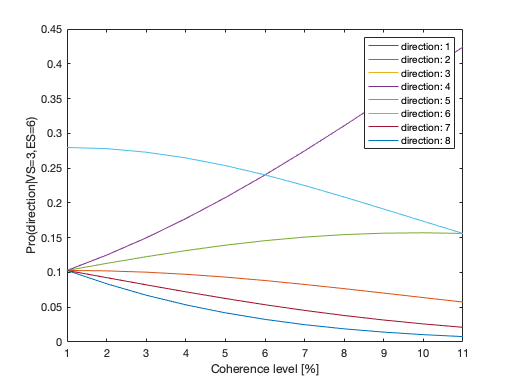

figure;
for i_idx = 1:size(i_SET,2)
    plot(p(i_idx,:),'DisplayName',['direction: ',num2str(i_idx)]);
    hold on;
end
xlabel('Coherence level [%]')
ylabel('Pro(direction|VS=3,ES=6)');
legend;

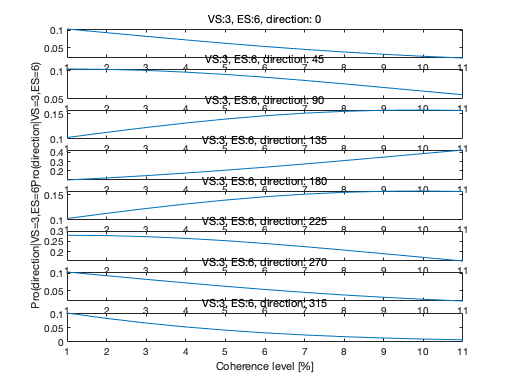



figure;
subplot(8,1,1);
plot(p(1,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(1))]);
%xlabel('Coherence level [%]')
%ylabel('Pro(direction|VS=3,ES=6)');


subplot(8,1,2); 
plot(p(2,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(2))]);
%xlabel('Coherence level [%]')
%ylabel('Pro(direction|VS=3,ES=6)');

subplot(8,1,3); 
plot(p(3,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(3))]);
%xlabel('Coherence level [%]')
ylabel('Pro(direction|VS=3,ES=6)');

subplot(8,1,4); 
plot(p(4,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(4))]);
%xlabel('Coherence level [%]')
%ylabel('Pro(direction|VS=3,ES=6)');

subplot(8,1,5); 
plot(p(5,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(5))]);
%xlabel('Coherence level [%]')
%ylabel('Pro(direction|VS=3,ES=6)');

subplot(8,1,6); 
plot(p(6,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(6))]);
xlabel('Coherence level [%]')
ylabel('Pro(direction|VS=3,ES=6)');

subplot(8,1,7); 
plot(p(7,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(7))]);
%xlabel('Coherence level [%]')
%ylabel('Pro(direction|VS=3,ES=6)');

subplot(8,1,8); 
plot(p(8,:));
title(['VS:3, ES:6, direction: ',num2str(i_SET(8))]);
xlabel('Coherence level [%]')

%ylabel('Pro(direction|VS=3,ES=6)');

